## Model Identification 

This is a pose model calibration script.

The script utilizies a matlab structrue (Which are time syncronized matlab structures) to calibrate the pose base models for estimation. The script utlizes least squares approach (lsqr) to find the model calibration parameters 'k' and 'm' to be fit in the models such that :

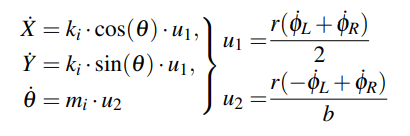

One may chose to ignore this script if their models are readily available in the above format.


clc
clear

load('TSynNL.mat')

Smoothening the GPS trajetories.

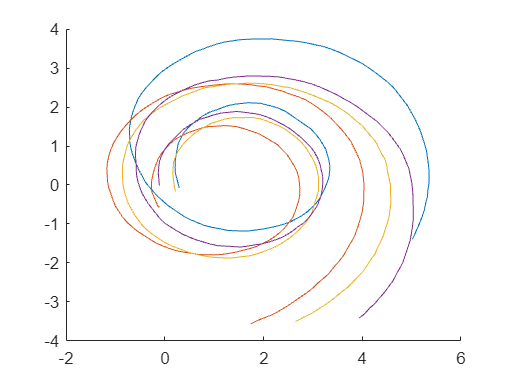

figure
hold on
for i = [2,4,6,8]
    k_t = find(TSyn(i).data.LeftWheel(1,:)>0);
    X = movmean(TSyn(i).data.enu_x_head(k_t),1);
    Y = movmean(TSyn(i).data.enu_y_head(k_t),1);
    theta = headingFromXY([X' Y']);
    theta = movmean(theta,1);
    plot(X,Y)
end

Converting the Postion based GPS trajectories to Global Velocity Trajectories

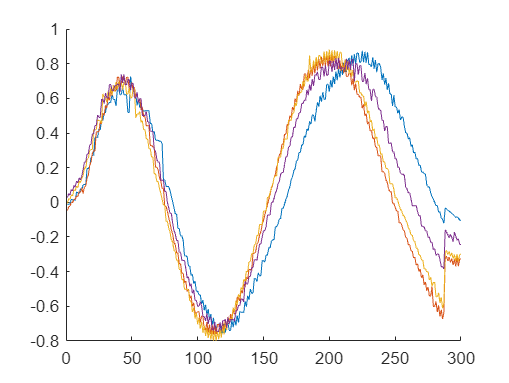

for i = 1:8
    k_t = find(TSyn(i).data.LeftWheel(1,:)>0);
    X = movmean(TSyn(i).data.enu_x_head(k_t),25);
    Y = movmean(TSyn(i).data.enu_y_head(k_t),25);
    theta = headingFromXY([X' Y']);
    theta = movmean(theta,25);

    data(i).X = X - X(1);
    data(i).Y = Y - Y(1);
    data(i).theta = theta - theta(1);
    data(i).u1 = (0.165/2).*(TSyn(i).data.LeftWheel(1,k_t) + TSyn(i).data.RightWheel(1,k_t));
    data(i).u2 = (0.165/0.555).*(-1*TSyn(i).data.LeftWheel(1,k_t) + TSyn(i).data.RightWheel(1,k_t));

    for j=1:(length(TSyn(i).data.enu_x_head(k_t))-1)
        X_dot(j) = (X(j+1)-X(j))/0.1;
        Y_dot(j) = (Y(j+1)-Y(i))/0.1;
        theta_dot(j) = (theta(j+1)-theta(i))/0.1;
    end
    X_dot(j+1) = X_dot(j);
    Y_dot(j+1) = Y_dot(j);
    theta_dot(j+1) = theta_dot(j);
    der(i).X_dot = X_dot;
    der(i).Y_dot = Y_dot;
    der(i).theta_dot = theta_dot;
    data(i).X_dot = X_dot;
    data(i).Y_dot = Y_dot;
    data(i).theta_dot = theta_dot;
    data(i).omega = -1*TSyn(i).data.IMU_fil_AngZ(k_t);
    clear X_dot Y_dot theta_dot X Y theta
end

figure
hold on
for i=[2,4,6,8]
    plot(der(i).X_dot)
    %mean(der(i).V_dot)
end


figure
hold on
for i=[2,4,6,8]
    plot(der(i).Y_dot)
    %mean(der(i).omega_dot)
end

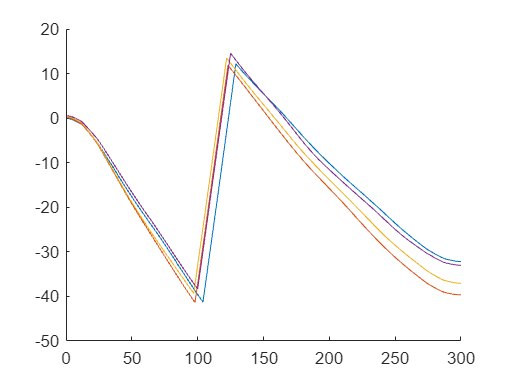


figure
hold on
for i=[2,4,6,8]
    plot(der(i).theta_dot)
    %mean(der(i).omega_dot)
end


%clear V_dot omega_dot


Model Fitting, one by one for each trajectory.

X = [];
Y = [];
phi_L1_dot = [];
phi_L2_dot = [];
phi_R1_dot = [];
phi_R2_dot = [];
X_dot = [];
Y_dot = [];
theta_dot = [];
tht = [];

% for i = 2
% 
%     %k_t = find(TSyn(i).data.LeftWheel(1,:)>0);
%     X = [X, TSyn(i).data.enu_x_head(k_t)];
%     Y = [Y, TSyn(i).data.enu_y_head(k_t)];
%     theta = headingFromXY([X' Y']);
%     theta = theta';
%     %theta = movmean(theta,1);
%     tht = [tht,theta];
%     phi_L1_dot = [phi_L1_dot, TSyn(i).data.LeftWheel(1,k_t)];
%     phi_L2_dot = [phi_L2_dot, TSyn(i).data.LeftWheel(1,k_t)];
%     phi_R1_dot = [phi_R1_dot, TSyn(i).data.RightWheel(1,k_t)];
%     phi_R2_dot = [phi_R2_dot, TSyn(i).data.RightWheel(1,k_t)];
%     %V_dot = [V_dot, ones(1,length(der(i).V_dot)).*mean(der(i).V_dot)];
%     X_dot = [X_dot, der(i).X_dot];
%     Y_dot = [Y_dot, der(i).Y_dot];
%     theta_dot = [theta_dot, der(i).theta_dot];
% end
    
    % Prepare the data
    %X = [V; omega];  % State vector [V; omega]
    %v = (0.165/2).*(phi_L1_dot + phi_R1_dot);
    %om = (0.165/0.555).*(-phi_L1_dot + phi_R1_dot);
    %X = [X;Y;theta];
    %U1 = [v.*cos(theta); v.*sin(theta);zeros(1,300)];  % Control input [phi_L_dot; phi_R_dot]
    %U2 = [zeros(1,300); zeros(1,300);om];

    i = 8;
    Y1 = data(i).X_dot;  % Output [V_dot; omega_dot]
    Z1 = data(i).u1 .* (-1.*sin(data(i).theta) .* (data(i).theta))' + cos(data(i).theta)';  % Combined matrix [X; U]
    %Z = U;

    Y2 = data(i).theta_dot;  % Output [V_dot; omega_dot]
    Z2 = data(i).u2;  % Combined matrix [X; U]
    
    % Solve Y = [A B] * Z using least-squares
    %K = Y1 / Z1;  % params will contain [A B] horizontally
    K = lsqr(Z1',Y1')

lsqr converged at iteration 1 to a solution with relative residual 0.96.


K = -0.1276

    %M = lsqr(Z2',Y2')
    M = mean((data(i).omega)/data(i).u2)

M = 0.4062

    
    % Extract A and B from the params matrix
    %A = params(:, 1:3);  % A matrix (2x2)
    %B = params(:, 4:6);  % B matrix (2x2)

    %A_mat(i).A = A;
    %B_mat(i).B = B;


% % Display the results
% disp('Estimated A matrix:');
% disp(A);
% disp('Estimated B matrix:');
% disp(B);

Saving the data one by one in the 'PosMul' structure. 

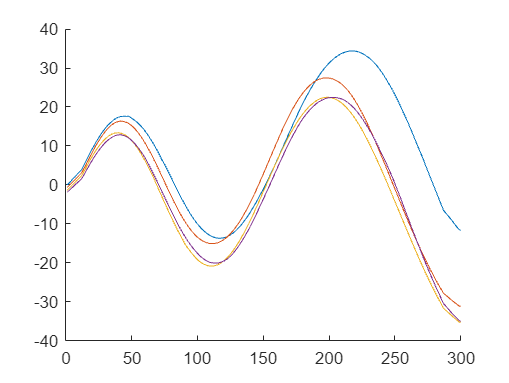

PosMul(8).K = K;
PosMul(8).M = M;
